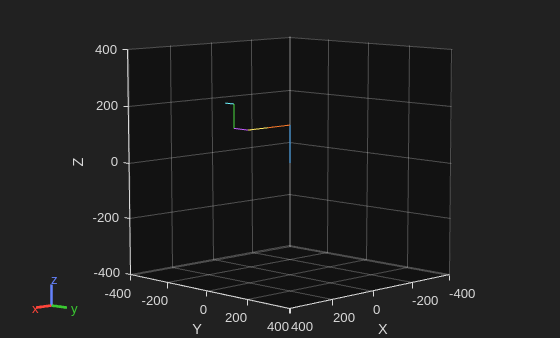

clc, clear
% Crear el modelo del robot con tus parámetros DH
dhparams = [
    0,      pi/2, 135, 0;
    110,     0,     0,  0;
    95,      0,     0,  0;
    0,      -pi/2,  70,  0;
    0,     pi/2,  85,  0;
    0,      0,     45,  0
];

robot = rigidBodyTree('DataFormat','column','MaxNumBodies', 6);

prevBodyName = 'base';
for i = 1:6
    body = rigidBody(['link' num2str(i)]);
    joint = rigidBodyJoint(['joint' num2str(i)], 'revolute');
    setFixedTransform(joint, dhparams(i,:), 'dh');
    body.Joint = joint;
    addBody(robot, body, prevBodyName);
    prevBodyName = body.Name;
end

% Mostrar el robot en su configuración inicial
show(robot);

%title('Robot en configuración inicial');

% Ahora asignamos un vector de coordenadas generalizadas (ángulos de juntas)
% Por ejemplo, puedes probar con algo arbitrario:
q = deg2rad([0; 90; 0; 0; 0; 0]);  % en radianes

% Mostrar el robot con esa configuración
%show(robot, q, 'PreservePlot', false);
%title('Robot con q dado');